
stack = readFileToStack(opt.filePath{1,1});

% %indexes of ROI within the mask of interest (polygon)
[iroi, jroi] = find(opt.vectorPositions);

k = 2;
TOIFOV = stack(:,:,floor(1+(k-1)/opt.fracTOIshift*opt.TOIsize):floor(opt.TOIsize*(1+((k-1)/opt.fracTOIshift))));

u = 1;
% Accessing the data of only the ROIs that are defined within the selected polygon
            i=iroi(u);
            j=jroi(u);
            
            % Define the data region (x,y,t) on which STICS will be applied
            regionanalyse = TOIFOV(floor(1+(i-1)/opt.fracROIshift*opt.ROIsize):floor(opt.ROIsize*(1+((i-1)/opt.fracROIshift))), floor(1+(j-1)/opt.fracROIshift*opt.ROIsize): floor(opt.ROIsize*(1+((j-1)/opt.fracROIshift))),:);

            % Apply regular cross-corr STICS
            [corrfn] = stics(regionanalyse, opt.tauLimit);    
            
[coeffGtime] = gaussfit(corrfn,'time',opt.pixelSize,'n',opt.fitRadius); coeffGtime

coeffGtime =     0.0059    0.5665    0.5665   -0.0004    0.0550    0.0550
    0.0051    0.6204    0.6204   -0.0003    0.0456    0.0692
    0.0045    0.6354    0.6354   -0.0003    0.0098    0.0569
    0.0043    0.6532    0.6532   -0.0003   -0.0317    0.0643
    0.0038    0.6949    0.6949   -0.0003    0.0009    0.1096


size(corrfn)

ans =     32    32     5


[Px, Sx] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),5))', 1); Px

Px =    -0.0009    0.0716


[Py, Sy] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),6))', 1); Py

Py =     0.0005    0.0397


[Ex, deltax] = polyval(Px, opt.timeFrame*(1:size(corrfn,3)), Sx)

Ex =     0.0530    0.0345    0.0159   -0.0026   -0.0212


deltax =     0.0283    0.0255    0.0245    0.0255    0.0283


xresid = squeeze(coeffGtime(1:size(corrfn,3),5))' - Ex

xresid =     0.0020    0.0111   -0.0061   -0.0291    0.0221


SSxresid = sum(xresid.^2)

SSxresid = 0.0015

SSxtotal = (length(squeeze(coeffGtime(1:size(corrfn,3),5))')-1 * var(squeeze(coeffGtime(1:size(corrfn,3),5))'))

SSxtotal = 4.9988

xrsq = 1 - SSxresid/SSxtotal

xrsq = 0.9997

SSxresid/SSxtotal

ans = 2.9942e-04

[Ey, deltay] = polyval(Py, opt.timeFrame*(1:size(corrfn,3)), Sy)

Ey =     0.0501    0.0606    0.0710    0.0814    0.0918


deltay =     0.0220    0.0198    0.0190    0.0198    0.0220


yresid = squeeze(coeffGtime(1:size(corrfn,3),6))' - Ey

yresid =     0.0049    0.0086   -0.0141   -0.0171    0.0177


SSyresid = sum(yresid.^2)

SSyresid = 9.0563e-04

SSytotal = (length(squeeze(coeffGtime(1:size(corrfn,3),6))')-1 * var(squeeze(coeffGtime(1:size(corrfn,3),6))'))

SSytotal = 4.9995

yrsq = 1 - SSyresid/SSytotal

yrsq = 0.9998

SSyresid/SSytotal

ans = 1.8114e-04

[P,S] = polyfit(coeffGtime(:,5),coeffGtime(:,6),1);
[Fit, Delta] = polyval(P,coeffGtime(:,5),S);
Resid = squeeze(coeffGtime(:,6)) - Fit

Resid =    -0.0093
    0.0033
   -0.0151
   -0.0149
    0.0360


SSresid = sum(Resid.^2)

SSresid = 0.0018

SStotal = (length(squeeze(coeffGtime(1:size(corrfn,3),6))')-1 * var(squeeze(coeffGtime(1:size(corrfn,3),6))'));
Rsq = 1 - SSresid/SStotal

Rsq = 0.9996

SSresid/SStotal

ans = 3.6903e-04

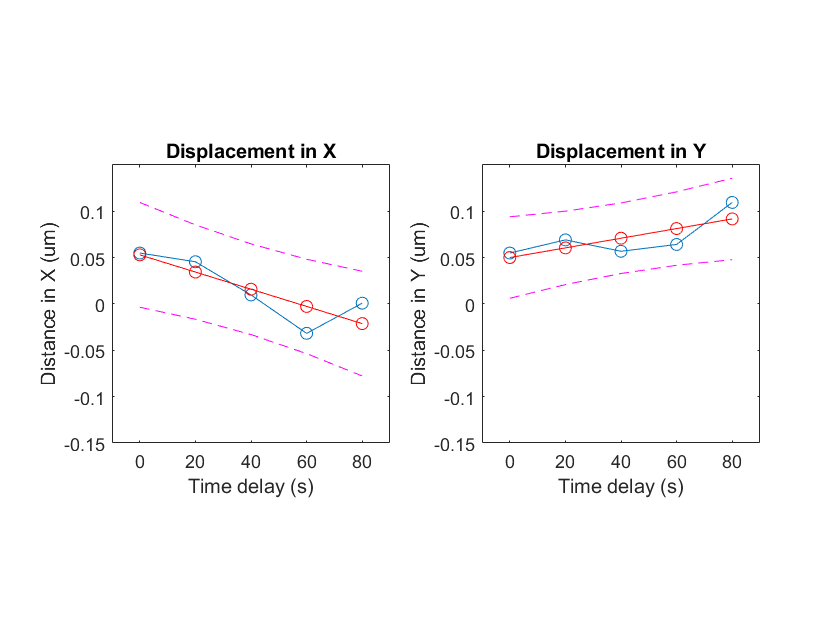

figure;
subplot(1,2,1);
plot(0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,...
    coeffGtime(:,5), "o-"); title('Displacement in X'); 
xlabel('Time delay (s)'); ylabel('Distance in X (um)'); axis square
ylim([-0.15 0.15]);
xlim([-10, 90]);
hold on;

plot(0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,...
    Ex,"-or");
plot(0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,Ex+2*deltax,'m--',...
        0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,Ex-2*deltax,'m--');
hold off;

subplot(1,2,2);
plot(0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,...
    coeffGtime(:,6), "o-"); title('Displacement in Y'); 
xlabel('Time delay (s)'); ylabel('Distance in Y (um)'); axis square
hold on;
plot(0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,...
    Ey,"-or");
plot(0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,Ey+2*deltay,'m--',...
        0:opt.timeFrame:opt.timeFrame*size(coeffGtime,1)-1,Ey-2*deltay,'m--');

ylim([-0.15 0.15]);
xlim([-10, 90]);
hold off;

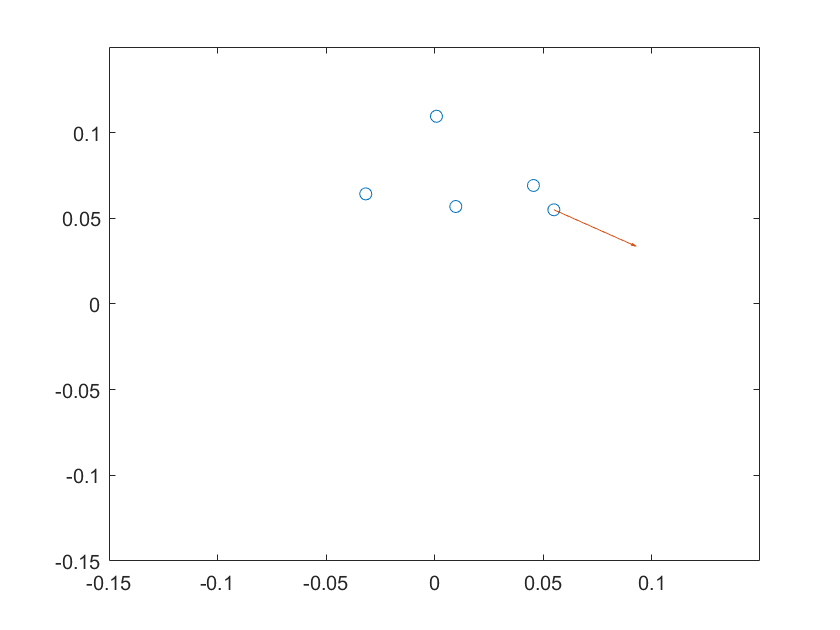


figure;
plot(coeffGtime(:,5),coeffGtime(:,6),'o'); 
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);             
hold on;
% plot(coeffGtime(:,5), Ey,"-or");
% plot(Ex,coeffGtime(:,6),"-or");
% plot(coeffGtime(:,5),Fit,"-og");
% plot(coeffGtime(:,5),Fit+2*Delta,'m--',...
%         coeffGtime(:,5),Fit-2*Delta,'m--');
quiver(coeffGtime(1,5),coeffGtime(1,6),-Px(1)*1/opt.pixelSize*size(corrfn,3),-Py(1)*1/opt.pixelSize*size(corrfn,3));

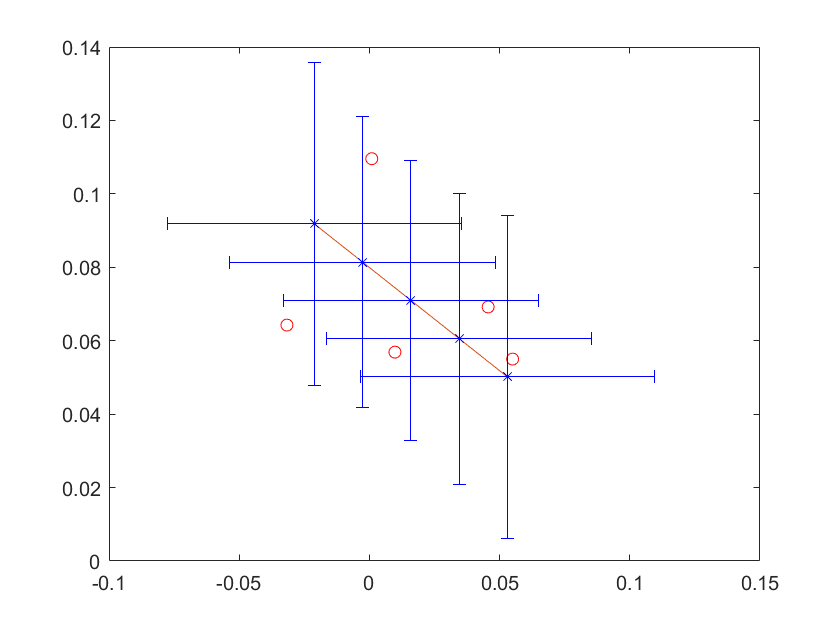

                figure;
plot(coeffGtime(:,5), coeffGtime(:,6), "or"); hold on
plot([Ex(1), Ex(end)], [Ey(1), Ey(end)]);
xpos = 2.*deltax; xneg = xpos;
ypos = 2.*deltay; yneg = ypos;
errorbar(Ex, Ey, yneg, ypos, xneg, xpos, "*b")


plot(coeffGrotated(:,5), coeffGrotated(:,6), "og");

Unrecognized function or variable 'coeffGrotated'.

plot([ExR(1), ExR(end)], [EyR(1), EyR(end)]);
xposR = 2.*deltaxR; xnegR = xpos;
yposR = 2.*deltayR; ynegR = ypos;
errorbar(ExR, EyR, ynegR, yposR, xnegR, xposR, "+m")

title('Displacement in XY'); 
xlabel('Distance in X (um)'); ylabel('Distance in Y (um)');
% xlim([-opt.pixelSize*opt.ROIsize/16, opt.pixelSize*opt.ROIsize/16]); 
% ylim([-opt.pixelSize*opt.ROIsize/16, opt.pixelSize*opt.ROIsize/16]);
axis ij; hold off;

% [Px, Sx] = polyfit(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),5))', 1); Px
plot(opt.timeFrame*(1:size(corrfn,3)), squeeze(coeffGtime(1:size(corrfn,3),5))'); hold on;
xlim = [-10, max(opt.timeFrame*(1:size(corrfn,3)))];
plot(opt.timeFrame*(1:size(corrfn,3)), polyval(Px, opt.timeFrame*(1:size(corrfn,3))));hold off

velocityMap{k}.Px(i,j)